# MGRIT advection driver

MGRIT experiment for advection with optimized coarse time-stepping

## Problem generation

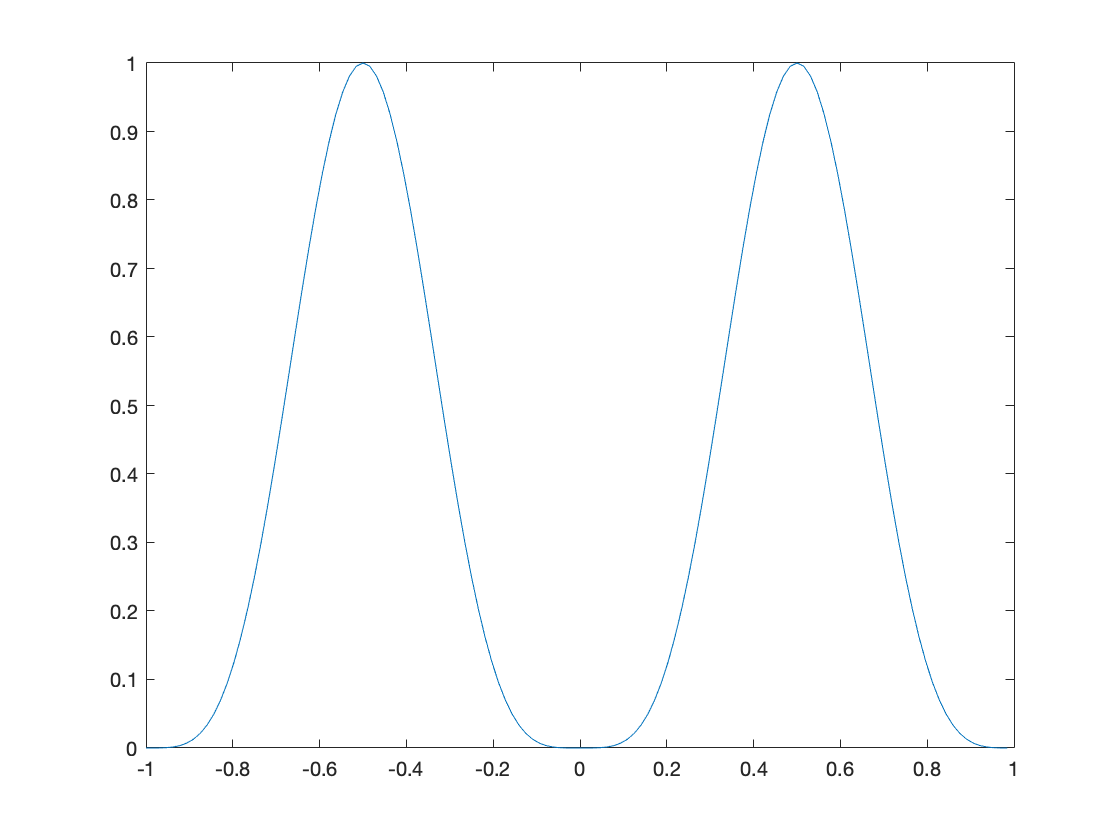

Nx = 128;
h = 2/128;
dt = 1/64;
cr = 0.85;
x = linspace(-1,1,Nx+1);
x = x(1:end-1);
y = sin(pi*x).^4;
plot(x,y)

## Optimization of coarse stepping


$$\Psi =\Phi^{16}$$


#### ERK1+U1


$$u^{n+1}_i=(1-c\frac{\Delta t}{\Delta x})u^n_i + c\frac{\Delta t}{\Delta x}u^n_{i-1}$$


cmax = 1;
c = cr*cmax;
Phi = (1-c*dt/h) .* eye(Nx);
Phi(1,Nx) = c*dt/h;
for i = 1:Nx-1
    Phi(i+1,i) = c*dt/h;
end
Psi = Phi^16;
plot(1:36,abs(Psi(1:36,1)),'k-o')
hold on

#### ERK2+U2

cmax = 1/2;
c = cr  * cmax;
coeff = [3,-4,1];
k1 = -coeff ./ (2*h);
u1 = [1 0 0] + c * dt .* k1;
coeff2 = [coeff,0,0;0,coeff,0;0,0,coeff];
k2 = -u1*coeff2 ./ (2*h);
s = [1 0 0 0 0] + c * dt .* (0.5 .* [k1 0 0] + 0.5 .*k2);
s = [s';zeros(Nx-5,1)];
for i = 1:Nx
    Phi(:,i) = s;
    s = circshift(s,1);
end
Psi = Phi^16;
plot(1:36,abs(Psi(1:36,1)),'r-x')

#### ERK3+U3

cmax = 1.62589;
c = cr * cmax;
U = zeros(1,Nx);
U(1) = 1;
S = ERK3_U3(U,h,c*dt)';
for i = 1:Nx
    Phi(:,i) = S;
    S = circshift(S,1);
end
Psi = Phi^16;
plot(1:36,abs(Psi(1:36,1)),'b->')

#### ERK4+U4

cmax = 1.04449;
c = cr * cmax;
U = zeros(1,Nx);
U(1) = 1;
S = ERK4_U4(U,h,c*dt)';
for i = 1:Nx
    Phi(:,i) = S;
    S = circshift(S,1);
end
Psi = Phi^16;
plot(1:36,abs(Psi(1:36,1)),'g-p')

#### ERK5+U5

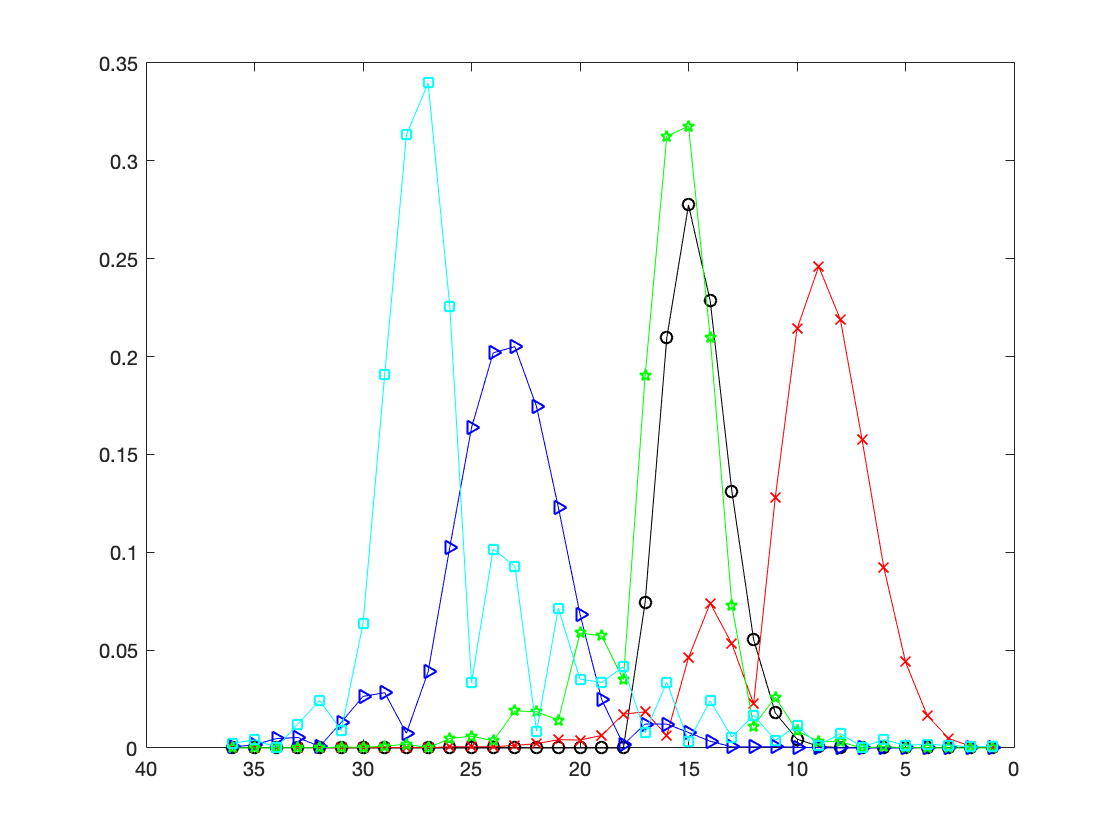

cmax = 1.96583;
c = cr * cmax;
U = zeros(1,Nx);
U(1) = 1;
S = ERK5_U5(U,h,c*dt)';
for i = 1:Nx
    Phi(:,i) = S;
    S = circshift(S,1);
end
Psi = Phi^16;
plot(1:36,abs(Psi(1:36,1)),'c-s')
set(gca,'Xdir','reverse')
hold off